# Polarization

Define a 2D-polarization vector


$$\mathbf{u} = (\cos \theta,e^{i\phi}\sin \theta)$$


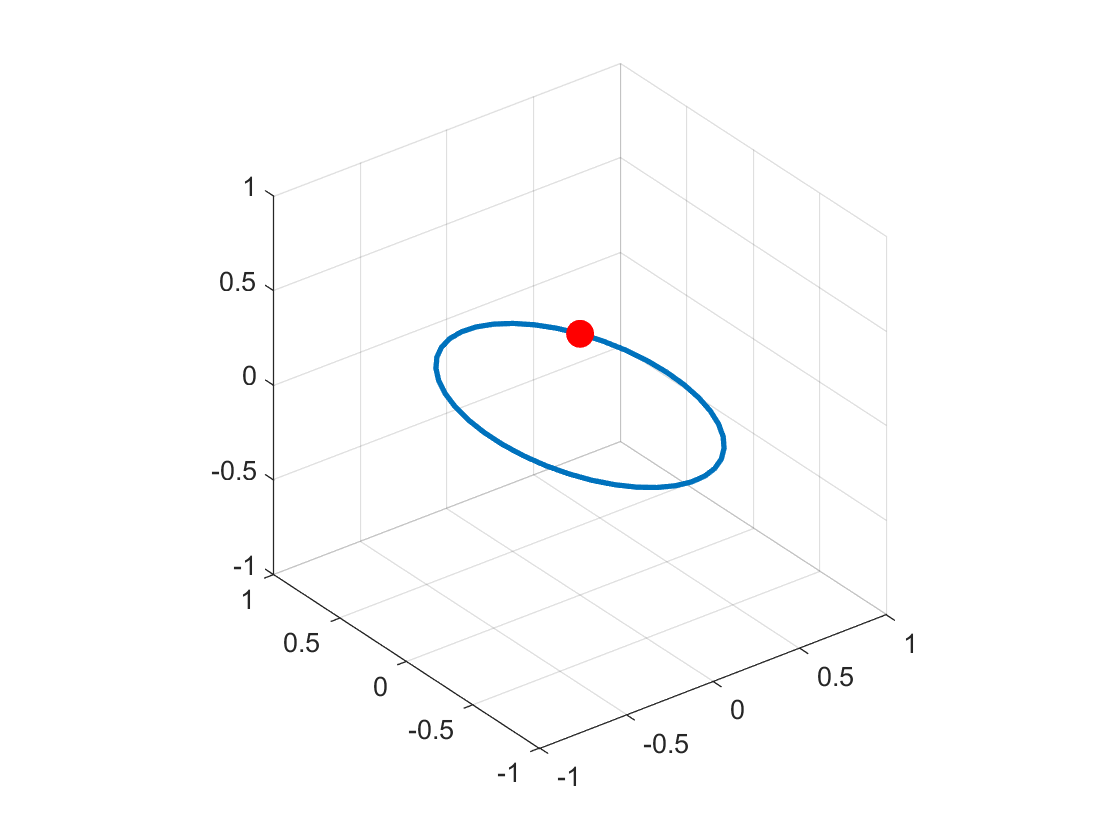

PolTheta = pi/3;
PolPhi = pi/2;
Pol = [cos(PolTheta),sin(PolTheta)*exp(1i*(PolPhi)),0];
showPol(Pol)

# Polarization decomposition

We can decompose arbitrary polarization vector (complex unit vector) to the angular basis along certain axis. For a given axis direction $\hat{n}(\theta,\phi) = (\cos\theta\sin\phi,\sin\theta\sin\phi,\cos\phi)$, the polarization component is defined as


$$\hat{\pi} = \hat{n}_0(\theta,\phi) = (\cos\theta\sin\phi,\sin\theta\sin\phi,\cos\phi) \\
\hat{n}_1 = \hat{n}_0(\theta,\phi+\frac{\pi}{2})\\
\hat{n}_2 = \hat{\pi}\times \hat{n}_1 \\
\hat{\sigma}_+ = \frac{\hat{n}_1-i\hat{n}_2}{\sqrt{2}} \\
\hat{\sigma}_- = \frac{\hat{n}_1+i\hat{n}_2}{\sqrt{2}}$$


The polarization decomposition


$$\vec{p}  =p_0\hat{n}_0 +p_1\hat{n}_1+p_2\hat{n}_2\\= p_0\hat{n}_0+p_+\hat{\sigma}_++p_-\hat{\sigma}_-$$


One can derive


$$p_0 = \vec{p}\cdot\hat{n}_0 \\
p_+ = \frac{\vec{p}\cdot\hat{n}_1+i\vec{p}\cdot\hat{n}_2}{\sqrt{2}} \\
p_- = \frac{\vec{p}\cdot\hat{n}_1-i\vec{p}\cdot\hat{n}_2}{\sqrt{2}}$$


PolTheta = pi/4;
PolPhi = -pi/2;
Pol = [cos(PolTheta),sin(PolTheta)*exp(1i*(PolPhi)),0];
PolCir = decomPol(Pol,[0,0,1])

PolCir =    0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 - 0.0000i


1i*cross(conj(Pol),Pol)

ans =      0     0     1


# Waveplates

Rotation of coordinates


$$R(\beta) = \left(
\begin{array}{cc}
\cos\beta & \sin\beta\\
-\sin\beta & \cos\beta
\end{array}\right)$$


An arbitrary waveplate transforms polarization by introducing a phase shift betwee two axis


$$S(0) = \left(
\begin{array}{cc}
e^{-i\gamma/2} & 0 \\
0 & e^{i\gamma/2}
\end{array}\right)$$


If rotated by angle $\beta$, the arbitrary waveplate transforms polarization


$$S(\beta) = R(-\beta)S(0)R(\beta) = \left(
\begin{array}{cc}
\cos\frac{\gamma}{2}+i\cos 2\beta\sin\frac{\gamma}{2} & i\sin 2\beta \sin\frac{\gamma}{2} \\
 i\sin 2\beta \sin\frac{\gamma}{2} & \cos\frac{\gamma}{2}-i\cos 2\beta\sin\frac{\gamma}{2}
\end{array}\right)$$


In the case of half-waveplate and quarter-waveplate


$$H(\beta) = \left(\begin{array}{cc}
\cos 2\beta & \sin 2\beta \\
\sin 2\beta & -\cos 2\beta
\end{array}\right)$$



$$Q(\beta) = \frac{1}{\sqrt{2}}\left(\begin{array}{cc}
1+i\cos 2\beta & i\sin 2\beta \\
i\sin 2\beta & 1-i\cos 2\beta
\end{array}\right)$$


HWP = @(x) getArbWP(pi,x);
QWP = @(x) getArbWP(pi/2,x);
disp(QWP(-pi/4)*HWP(-pi/2)*QWP(pi/4))

   0.0000 - 0.0000i   1.0000 - 0.0000i
  -1.0000 - 0.0000i   0.0000 + 0.0000i



disp(QWP(pi/4)*HWP(pi/2)*QWP(pi/4))

  -0.0000 - 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0000 + 1.0000i



disp(QWP(pi/2)*HWP(pi/4)*QWP(pi/2))

  -0.0000 + 0.0000i  -0.0000 + 1.0000i
   0.0000 + 1.0000i  -0.0000 - 0.0000i



A = sqrt(2)/2*[1,1i;1i,1];
syms x
HWP = @(x) [cos(2*x),sin(2*x);sin(2*x),-cos(2*x)];
A*HWP(x)*A

$$ans = \begin{array}{l} \left(\begin{array}{cc} \frac{\sqrt{2}\,\sigma_{2}\,\mathrm{i}}{2}+\frac{\sqrt{2}\,\sigma_{4}}{2} & \frac{\sqrt{2}\,\sigma_{2}}{2}+\frac{\sqrt{2}\,\sigma_{4}\,\mathrm{i}}{2}\\ \frac{\sqrt{2}\,\sigma_{3}}{2}+\frac{\sqrt{2}\,\sigma_{1}\,\mathrm{i}}{2} & \frac{\sqrt{2}\,\sigma_{3}\,\mathrm{i}}{2}+\frac{\sqrt{2}\,\sigma_{1}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{\sqrt{2}\,\cos\left(2\,x\right)}{2}+\frac{\sqrt{2}\,\sin\left(2\,x\right)\,\mathrm{i}}{2}\\ \sigma_{2}=\frac{\sqrt{2}\,\sin\left(2\,x\right)}{2}-\frac{\sqrt{2}\,\cos\left(2\,x\right)\,\mathrm{i}}{2}\\ \sigma_{3}=\frac{\sqrt{2}\,\sin\left(2\,x\right)}{2}+\frac{\sqrt{2}\,\cos\left(2\,x\right)\,\mathrm{i}}{2}\\ \sigma_{4}=\frac{\sqrt{2}\,\cos\left(2\,x\right)}{2}+\frac{\sqrt{2}\,\sin\left(2\,x\right)\,\mathrm{i}}{2} \end{array}$$